warning on backtrace

### 1. Read the video file and define its size and frames

videosquence = 'foreman_cif-1.yuv';     % original yuv file
width = 352;                            % original yuv width
height = 288;                           % original yuv height
nframes = 10;                           % number of yuv frames
blocked_frame_cell_array = cell(1,300); % Storage for blocked frame, no meaningful use in algo., good visualizer

% extract Y, padding and blocking
A1_Q3_extract_YOnly(videosquence, height, width, nframes);

Y-only files Y!


### 2. Exercise1-a. ﻿For every specific target set of configs...

% I_periods = [1, 4, 10];
% searchRanges = [1, 4, 8];
% ns = [1, 2, 3];
% nRefFrames = [1, 2, 3, 4];
% VBSEnables = [false, true];
% FMEEnables = [false, true];
% FastMEs = [false, true];

I_periods = [4];
searchRanges = [4];
ns = [1];
nRefFrames = [1];
VBSEnables = [false];
FMEEnables = [false];
FastMEs = [false]; 

combinations = A3_combineConfigs(I_periods, searchRanges, ns, ...
    nRefFrames, VBSEnables, FMEEnables, FastMEs);

combinations(:, 5) = logical(combinations(:, 4));
combinations(:, 6) = logical(combinations(:, 5));
combinations(:, 7) = logical(combinations(:, 6));

filename_prefix = "A3_Q1_a_";

QPs = 0:9;
blockSizes = [4, 8, 16];
RCflag = false;
targetBR = inf;

IAverageBitCounts = zeros(length(blockSizes), length(QPs));
PAverageBitCounts = zeros(length(blockSizes), length(QPs));

for blockSize_idx = 1:length(blockSizes)
    blockSize = blockSizes(blockSize_idx);

    for QP_idx = 1:length(QPs)

        QP_value = QPs(QP_idx);
        iTotalBitCounts = 0;
        iTotalRowCounts = 0;
        pTotalBitCounts = 0;
        pTotalRowCounts = 0;

        fprintf('Processing QPs: %d with block size: %d.\n', QP_value, blockSize);
        for comb_idx = 1:size(combinations, 1)
            [paddedWidth, paddedHeight] = A1_Q3_paddingAndBlocking(width, height, blockSize, ...
                blocked_frame_cell_array, nframes);
            I_period = combinations(comb_idx, 1);
            searchRange = combinations(comb_idx, 2);
            n = combinations(comb_idx, 3);
            
            nRefFrame = combinations(comb_idx, 4);
            VBSEnable = combinations(comb_idx, 5);
            FMEEnable = combinations(comb_idx, 6);
            FastME = combinations(comb_idx, 7);

            isIFrame = @(x) mod(x, I_period) == 0;
            iFrameIdx = arrayfun(isIFrame, 1:nframes);
            pFrameIdx = arrayfun(@(x) ~isIFrame(x), 1:nframes);
        
            [~, bitConsumptionPerFrame, rowBlockCountPerFrame] = A3_Encoding( ...
                filename_prefix, nframes, paddedWidth, paddedHeight, ...
                blockSize, height, width, searchRange, n, I_period, QP_value, ...
                nRefFrames, VBSEnable, MRFoverlay, FMEEnable, FastME, ...
                RCflag, targetBR, [], [], [], []);

            bitConsumptionsInIFrame = bitConsumptionPerFrame(iFrameIdx);
            rowBlockCountInIFrame = rowBlockCountPerFrame(iFrameIdx);
            iTotalBitCounts = iTotalBitCounts + sum(bitConsumptionsInIFrame);
            iTotalRowCounts = iTotalRowCounts + sum(rowBlockCountInIFrame);

            bitConsumptionsInPFrame = bitConsumptionPerFrame(pFrameIdx);
            rowBlockCountInPFrame = rowBlockCountPerFrame(pFrameIdx);
            pTotalBitCounts = pTotalBitCounts + sum(bitConsumptionsInPFrame);
            pTotalRowCounts = pTotalRowCounts + sum(rowBlockCountInPFrame);

            fprintf("%d %d %d %d.\n", iTotalBitCounts, iTotalRowCounts, ...
                pTotalBitCounts, pTotalRowCounts);
        end

        IAverageBitCounts(blockSize_idx, QP_idx) = round(iTotalBitCounts / iTotalRowCounts, 0);
        PAverageBitCounts(blockSize_idx, QP_idx) = round(pTotalBitCounts / pTotalRowCounts, 0);
    end
end

Processing QPs: 0 with block size: 4.


Y frame is split to blocks and padded as needed!


1082259 144 4204386 576.


Processing QPs: 1 with block size: 4.


Y frame is split to blocks and padded as needed!


866670 144 3350935 576.


Processing QPs: 2 with block size: 4.


Y frame is split to blocks and padded as needed!


607236 144 2373088 576.


Processing QPs: 0 with block size: 8.


Y frame is split to blocks and padded as needed!


983682 72 3870329 288.


Processing QPs: 1 with block size: 8.


Y frame is split to blocks and padded as needed!


735404 72 2907575 288.


Processing QPs: 2 with block size: 8.


Y frame is split to blocks and padded as needed!


510453 72 2045107 288.


Processing QPs: 0 with block size: 16.


Y frame is split to blocks and padded as needed!


962035 36 3809685 144.


Processing QPs: 1 with block size: 16.


Y frame is split to blocks and padded as needed!


712753 36 2842361 144.


Processing QPs: 2 with block size: 16.


Y frame is split to blocks and padded as needed!


504944 36 2022598 144.



disp(IAverageBitCounts);

        7516        6019        4217
       13662       10214        7090
       26723       19799       14026



disp(PAverageBitCounts);

        7299        5818        4120
       13439       10096        7101
       26456       19739       14046




save(strcat(filename_prefix, 'IAverageBitCounts.mat'), 'IAverageBitCounts'); 
save(strcat(filename_prefix, 'PAverageBitCounts.mat'), 'PAverageBitCounts');

T_IAverageBitCounts = array2table(IAverageBitCounts, ...
    'VariableNames', strcat("QP_", string(QPs)));
rowNames = strcat("Average_BitCount_", string(blockSizes), ...
    "x", string(blockSizes));
T_IAverageBitCounts.Properties.RowNames = rowNames;
disp(T_IAverageBitCounts);

                              QP_0     QP_1     QP_2 
                              _____    _____    _____

    Average_BitCount_4x4       7516     6019     4217
    Average_BitCount_8x8      13662    10214     7090
    Average_BitCount_16x16    26723    19799    14026




P_IAverageBitCounts = array2table(PAverageBitCounts, ...
    'VariableNames', strcat("QP_", string(QPs)));
rowNames = strcat("Average_BitCount_", string(blockSizes), ...
    "x", string(blockSizes));
P_IAverageBitCounts.Properties.RowNames = rowNames;
disp(P_IAverageBitCounts);

                              QP_0     QP_1     QP_2 
                              _____    _____    _____

    Average_BitCount_4x4       7299     5818     4120
    Average_BitCount_8x8      13439    10096     7101
    Average_BitCount_16x16    26456    19739    14046



### 3. Exercise1-b. ﻿Add an “RCflag” to the encoder configs...

RCflag = true;
targetBR = 1140480;
frame_rows = 288 % simulate a real frame

frame_rows = 288

blocksize = 4;

rowBlockCounts = frame_rows / blocksize;
fps = 30

fps = 30


[budget] = A3_getRowBitBudget(RCflag, targetBR, rowBlockCounts, fps);
disp(budget);

   528



### 4. Exercise1-c. ﻿Your RC algorithm should operate as follows...

QPs = 0:9

QPs =      0     1     2     3     4     5     6     7     8     9


blocksizes = [2, 4, 8, 16, 32, 64];

budgetTable_example = [
    9684, 8660, 7271, 6801, 6559, 6045, 5553, 5438, 4639, 4124;
    9478, 9197, 8846, 7758, 7467, 4020, 2299, 2245, 2233, 2158;
    9062, 8522, 8086, 7034, 5650, 5571, 5557, 5270, 2318, 2165;
    9549, 7556, 6868, 6712, 5378, 5119, 4993, 4402, 4082, 3655;
    9953, 9682, 8467, 8437, 8434, 7030, 6768, 4261, 2966, 2544;
    9315, 7778, 7153, 5255, 5154, 4919, 4890, 3506, 3380, 2431
];

targetBlockSize = 8;
targetBudget = 4000;

[optimalQP, averageBitCount] = A3_findQPForBudget(targetBudget, targetBlockSize, ...
    blocksizes, QPs, budgetTable_example)

optimalQP = 8

averageBitCount = 2318

disp(optimalQP);

     8



disp(averageBitCount);

        2318



filename_prefix = "A3_Q1_ex_c_Zout_";
nframes = 10;
blockSize = 8;

[paddedWidth, paddedHeight] = A1_Q3_paddingAndBlocking(width, height, blockSize, ...
    blocked_frame_cell_array, nframes);

Y frame is split to blocks and padded as needed!



searchRange =2;
n = 1;
I_period = 4;
QP_values = 2;
nRefFrames = 1;
VBSEnable = false;
MRFoverlay = 0;
FMEEnable = false;
FastME = false;

RCflag = true;
targetBR = 2.4 * 1140480 * 3;

blockSizeCollections = [2, 4, 8, 16, 32, 64];
QPValueCollections = 0:9;

iFrameAverageBitCount = [
    9684, 8660, 7271, 6801, 6559, 6045, 5553, 5438, 4639, 4124;
    9478, 9197, 8846, 7758, 7467, 4020, 2299, 2245, 2233, 2158;
    9062, 8522, 8086, 7034, 5650, 5571, 5557, 5270, 2318, 2165;
    9549, 7556, 6868, 6712, 5378, 5119, 4993, 4402, 4082, 3655;
    9953, 9682, 8467, 8437, 8434, 7030, 6768, 4261, 2966, 2544;
    9315, 7778, 7153, 5255, 5154, 4919, 4890, 3506, 3380, 2431
];
pFrameAverageBitCount = [
    8265, 7773, 7661, 7359, 6524, 6052, 5959, 4550, 4530, 3591;
    7985, 7784, 5199, 5191, 4839, 4335, 4282, 3854, 3730, 3259;
    8518, 8305, 7524, 7315, 7102, 6906, 6354, 3994, 2719, 2171;
    9777, 9467, 7840, 7050, 6624, 6415, 6251, 5219, 4783, 3527;
    7752, 6057, 5636, 5558, 5209, 4572, 4161, 3400, 2651, 2276;
    8183, 7985, 7651, 5919, 5290, 4811, 4386, 3822, 3139, 2520
];

% Start the timer
tic;

[psnrValuesPerFrame, bitConsumptionPerFrame, rowBlockCountPerFrame] = A3_Encoding( ...
    filename_prefix, nframes, paddedWidth, paddedHeight, ...
    blockSize, height, width, searchRange, n, I_period, QP_values, ...
    nRefFrames, VBSEnable, MRFoverlay, FMEEnable, FastME, ...
    RCflag, targetBR, iFrameAverageBitCount, pFrameAverageBitCount, ...
    blockSizeCollections, QPValueCollections)

Processing I-frame 1 with frame budget: 821145.60
Processing P-frame 2 with frame budget: 881756.33
Processing P-frame 3 with frame budget: 934820.62
Processing P-frame 4 with frame budget: 998783.43
Processing I-frame 5 with frame budget: 1083854.50
Processing P-frame 6 with frame budget: 1245725.60
Processing P-frame 7 with frame budget: 1444154.50
Processing P-frame 8 with frame budget: 1772633.00
Processing I-frame 9 with frame budget: 2405082.00
Processing P-frame 10 with frame budget: 4532312.00


psnrValuesPerFrame =    42.7226   48.4384   47.5109   47.4067   42.7801   48.4827   47.5401   47.3586   42.6762   48.3730


bitConsumptionPerFrame =       275649      457242      487081      488357      274499      452010      458719      507735      277852      449258


rowBlockCountPerFrame =      1     1     1     1     1     1     1     1     1     1



% Stop the t ammer and display the elapsed time
elapsedTime = toc;                     
fprintf('Total encoding time: %.2f seconds\n', elapsedTime);

Total encoding time: 3.47 seconds



% Compute and display average PSNR across all frames
averagePSNR = mean(psnrValuesPerFrame);
fprintf('Average PSNR for the entire video: %.2f dB\n', averagePSNR);

Average PSNR for the entire video: 46.33 dB


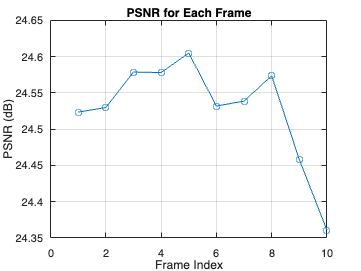


% Plot PSNR values over time (per frame)
figure;
plot(1:nframes, psnrValues, '-o');
xlabel('Frame Index');
ylabel('PSNR (dB)');
title('PSNR for Each Frame');
grid on;

### 5. ﻿Exercise1-d. ﻿Note that you need to formulate a way to communicate the QP values...